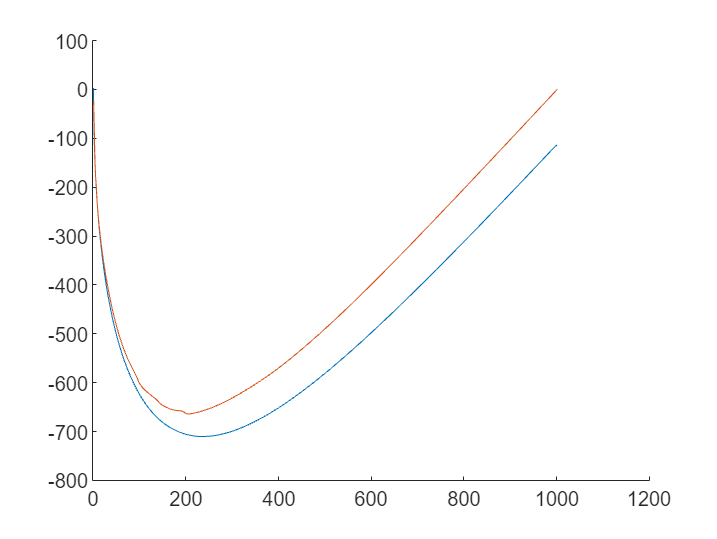

load comsol_data\socsurfn_linear.txt;
load comsol_data\socsurfp_linear.txt;

Dsn=3.9e-14;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=8e-6;

epssn=0.471;
epssp=0.297;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

Lsum=Ln+Ls+Lp;

cs0neg=14870;
cs0pos=3900;

csmaxneg=26390;
csmaxpos=22860;

A=1;
Rohm=6e-3;

F=96485.33289;

Qn=A*Ln*epssn*csmaxneg*F/3600;  %Ah
Qp=A*Lp*epssp*csmaxpos*F/3600;  %Ah

soc0n=cs0neg/csmaxneg;
soc0p=cs0pos/csmaxpos;

k=1:-0.001:0;
I=-17.5*k;
I_init=-17.5*[ones(1,length(I))];

csp=cumsum(-I)/Qp/3600*csmaxpos;
csn=cumsum(I)/Qn/3600*csmaxneg;

Jn_vector=I_init*Rsn/3/epssn/F/A/Ln;
Jp_vector=-I_init*Rsp/3/epssp/F/A/Lp;

csesurfn=socsurfn_linear(1:1001,2)*csmaxneg;
csesurfp=socsurfp_linear(1:1001,2)*csmaxpos;

dcsen_linear=csesurfn'-csn-cs0neg;

load net_sn.mat;
ypred=predict(net_sn,Jn_vector);
Ypred=ypred.*k;

figure(1);
clf;
hold on;
plot(dcsen_linear);
plot(Ypred);